# Examen Enero Final 2019

#### Introducción

La empresa en la que trabajamos tiene en desarrollo una nueva serie de consolas de grabación in-line digitales. Estas consolas deben proporcionar funcionalidades de automatización y es esta parte la que se nos ha encargado realizar. Deberemos programar un módulo de automatización, el cual, en base a una serie de parámetros registrados previamente, deberá aplicar los cambios adecuados en los diferentes elementos del canal que se está automatizando.

Los requerimientos de nuestra implementación son los siguientes: El módulo de automatización debe controlar un único canal de la consola. La consola empleará tantos módulos de automatización como canales disponga. El sonido debe procesarse por bloques de duración 10ms (aprox.), su longitud debe ser potencia de dos y no debe emplear solapamiento. La actualización de los parámetros del canal se realizará en cada comienzo de bloque.

A continuación, se detallan los elementos que deberá controlar el módulo de automatización: 

- Un ecualizador de 2 cortes. 

- Un fader que controla la ganancia del canal.

#### Problema 1. Preparación Inicial

Carga el fichero de sonido ‘prueba.wav’ y almacena su contenido en el vector ‘x’, y la frecuencia de muestreo en la variable fs. Determina el número de muestras que contiene (L), y el número de bloques de sonido (N) necesarios para procesar en su totalidad el fichero de audio cargado. Ten en cuenta que, si al final del fichero queda un bloque de datos incompleto, éste deberá ser desechado.

Por último, deberemos reservar memoria para la señal de salida del módulo ‘y’ que tendrá el mismo tamaño que la de entrada.

clc; clear all;

Cargamos y almacenamos el audio

[x, fs] = audioread('guitarra.wav');

Determinamos el número de muestras que contiene

L = length(x);

Y obtenemos el número de bloques de sonido del sistema

Primero obtenemos el tamaño de bloques

Nos dicen en la **introducción** que cada bloque tiene 10ms

Tam_Bloque = 2^(nextpow2(0.01*fs));

Para el número de bloques

Cuando me dan solapamiento 50% 2*Tam_Bloque-1

Si no me dicen nada, Longitud/Tamaño Bloque

N = floor(L/Tam_Bloque);

Ahora generamos la señal de salida 'y', con el mismo tamaño que la entrada

y = zeros(L, 1);

#### Problema 2. Diseño de los filtros de ecualización del canal

Los filtros que emplea la consola de mezcla son filtros paramétricos de segundo orden, los denominados peak filters. Los cuales poseen 3 parámetros por filtro: ganancia (G), Frecuencia Central (fc) y factor de calidad (Q). Implementar una función de Matlab que calcule los coeficientes de un filtro peak [b, a] teniendo como entrada los parámetros previos.

La función de transferencia de un filtro peak de segundo orden es: 

Dónde A2(z), es el siguiente filtro paso todo de segundo orden

Siendo c un factor que depende del ancho de banda del filtro (fb):

El resto de los parámetros se pueden determinar empleando las siguientes ecuaciones:

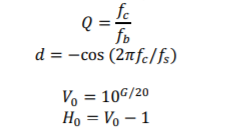

G = 10;
Fc = 1000;
Q = 0.8;
[b, a] = Coef_Filtro(G, fc, Q)

#### Problema 3. Cálculo de los parámetros de automatización

Para poder automatizar un canal, previamente debemos conocer los diferentes valores de todos los parámetros de cada uno de los elementos del canal. Por simplicidad, se nos proporcionan dos juegos de parámetros, el inicial (para el primer bloque) y el final (al que debemos llegar en el último bloque de sonido), el resto de bloques obtendrán su juego de parámetros interpolando linealmente. 

Crea una matriz de juegos de parámetros de dimensiones [7xN] en la cual deberás almacenar todos los juegos de parámetros obtenidos (una fila por bloque).

Parámetros iniciales: 

- Fader: G = -10 dB 

- Filtro 1: G = 3 dB, fc= 1000 Hz y Q = 1.41 

- Filtro 2: G = 6 dB, fc= 2500 Hz y Q = 2 

Parámetros finales: 

- Fader: G = 3 dB 

- Filtro 1: G = 6 dB, fc= 1500 Hz y Q = 1.2 

- Filtro 2: G = -2 dB, fc= 2500 Hz y Q = 2.5

Le damos un valor a N

N = 10;

Empezamos dando los paramétros iniciales

Fader_Inicio = -10;

Los del Filtro 1 Inicial

G_1_Ini = 3;
Fc_1_Ini = 1000;
Q_1_Ini = 1.41;

Los del Filtro 2 Inicial

G_2_Ini = 6;
Fc_2_Ini = 2500;
Q_2_Ini = 2;

Los parámetros finales

Fader_Final = 3;

Los del Filtro 1 Final

G_1_Fin = 6;
Fc_1_Fin = 1500;
Q_1_Fin = 1.2;

Los del Filtro 2 Final

G_2_Fin = -2;
Fc_2_Fin = 2500;
Q_2_Fin = 2.5;

Interpolamos los distintos valores, con la función linspace, que nos genera un vector entre 2 puntos de 100 muestras espaciadas equitativamente, si añadimos un número N al final genera un vector de N muestras

Interpolación del Fader

Fader = lisnpace(Fader_Inicio, Fader_Final, N);

Interpolación Filtro 1

G1 = linspace(G_1_Ini, G_1_Fin, N);
Fc1 = linspace(Fc_1_Ini, Fc_1_Fin, N);
Q1 = linspace(Q_1_Ini, Q_1_Fin, N);

Interpolación Filtro 2

G2 = linspace(G_2_Ini, G_2_Fin, N);
Fc2 = linspace(Fc_2_Ini, Fc_2_Fin, N);
Q2 = linspace(Q_2_Ini, Q_2_Fin, N);

Inicializamos la matriz con zeros

Matriz = zeros(7,N);

Ahora vamos asignando a cada fila de la Matriz un valor

Asignamos el Fader

Matriz(1,:) = Fader(:);

Asignamos el Filtro 1

Matriz(2,:) = G1(:);
Matriz(3,:) = Fc1(:);
Matriz(4,:) = Q1(:);

Asignamos el Filtro 2

Matriz(5,:) = G2(:);
Matriz(6,:) = Fc2(:);
Matriz(7,:) = Q2(:);

#### Problema 4 Automatización

Implementa un esquema de procesado por bloques, que cumpla con los requerimientos impuestos en la introducción.

Agrega al interior de este esquema el cálculo de los coeficientes de los filtros correspondientes al bloque que se está tratando.

Aplica la ecualización sobre el bloque de sonido así como la ganancia del fader y guarda el resultado en el vector de salida en las posiciones correspondientes.

Y = procesado(x, Matriz, Tam_Bloque);

#### Función del Problema 2

function  [b, a] = Coef_Filtro(G, fc, Q)

Le damos un valor a la frecuencia de muestreo

fs = 44100;

Las formulas que utilizaremos serán

Para calcular la fb

fb = fc/Q;

Para calcular la d

d = -cos(2*pi*fc/fs);

Para el cálculo de Vo

Vo = 10^(G/10);

Para calcular Ho

Ho = Vo-1;

Para hacer calcular la c, en Boost o en Cut. recordemos que

Si G vale más de 0,  se usará Boost

Si G vale menos de 0, se usará Cut

if G>0 %Boost
    c = (tan(pi*fb/fs)-1)/(tan(pi*fb/fs)+1);
else %Cut
    c = (tan(pi*fb/fs)-Vo)/(tan(pi*fb/fs)+Vo);
end

Ahora obtendremos los distintos valores de a y b

Este proceso se puede calcular en Matlab pero es más recomendable hacerlo a papel.

El proceso es el siguiente, la ecuación A2(z) la sustituimos en H(z) y despejamos hasta quedarnos con algo con la siguiente forma

Despejamos A(z) dentro de H(Z) y calculamos hasta que no podamos más. Como denominador tendremos las b y de numerador las a, lo que vaya con z-1 será b2 y a2, lo que vaya SIN z-1 será b1 y a1

a0 = 2;
a1 = 2 * d * (1 - c);
a2 = -2 * c;
b0 = 2 + Ho * (1 + c);
b1 = 2 * d * (1 - c);
b2 = (-2 * c) - Ho * (c + 1);

a = [a0 a1 a2];
b = [b0 b1 b2];
end

#### Función del problema 4

function Y = procesado(x, Matriz, Tam_Bloque)

Control de un único canal de la consola

[~,N] = size(Matriz);

Creamos un bucle para calcular  la aplicación de la ecualización

for i=1:N

Obtenemos la posición Inicial y Final del audio

    Pos_Inicial = (i-1)*(Tam_Bloque)+1;
    Pos_Final = Pos_Inicial + Tam_Bloque-1;

Cogemos la parte del Fader de la Matriz del problema 4

    Fader = Matriz(1,i);

Sacamos los valores de los coeficientes con la función del problema 2

    [b1, a1] = Coef_Filtro(Matriz(2,i), Matriz(3,i), Matriz(4,i));
    [b2, a2] = Coef_Filtro(Matriz(5,i), Matriz(6,i), Matriz(7,i));

Los juntamos en los vectores a y b

    a = [a1:a2];
    b = [b1:b2];

Creamos un bucle con el que calcularemos las posiciones correspondientes, lo haremos introduciendo a la función filtro los coeficientes b y a, el vector del audio x con el efecto del Fader

    for  j=1:2
        Y(Pos_Inicial:Pos_Final) = filter(b(j,:), a(j,:), x(Pos_Inicial, Pos_Final))*Fader
    end
end
end